**VSI power circuit**

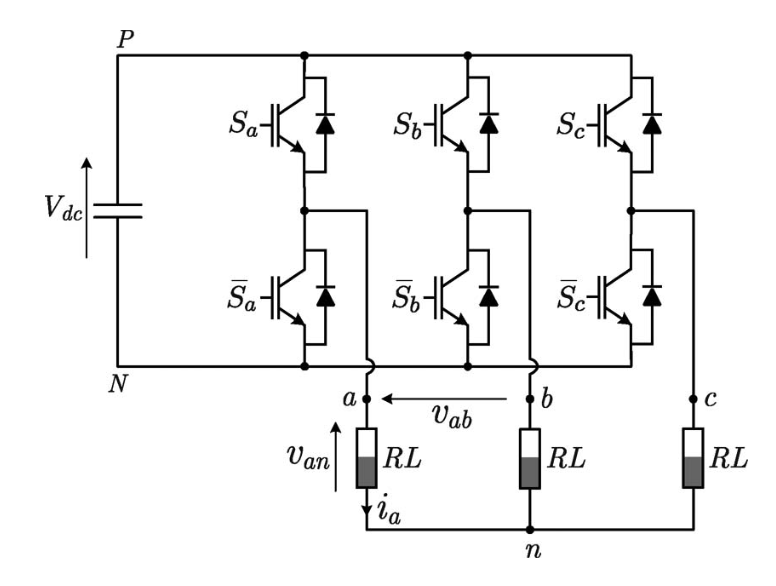

clc, clear all, close all

Ts = 1/1000; % secCALIBRAonds
Vd = 60; % voltage
Vdc = Vd;
R = 22.5;  %127 % ohms
L = 0.10 ; % henry
x_ref = [0.5 0.5]' ;

%**************************************************************************
%                       INIT SYSTEM PARAMETERS
%**************************************************************************
% transformada clark
K = 2/3 * [1 -1/2 -1/2; 0 sqrt(3)/2 -sqrt(3)/2] ;

I_2 = eye(2);

% state matrix
F = - R/L * I_2;
G = (Vd/(2*L)) * K;
A = expm(F*Ts); % matrix exponential
B = -F^(-1) * (I_2 - A) * G;

lambda = 0.01; % switch
lambda_i = 10 ; % current


uk=[0 0 0]';

switch_state = [
    0 0 0;
    0 0 1;
    0 1 0;
    0 1 1;
    1 0 0;
    1 1 0;
    1 0 1;
    1 1 1;
];

n = (size(switch_state));
n = n(1);
np=1;


%**************************************************************************
%**************************************************************************
%**************************************************************************
%**************************************************************************
%
% POSSIBILITIES
%
%**************************************************************************
% Condicao 0 inicial
x0 = [0 ; 0];
i_alfa = x0(1); i_beta = x0(2);
u0 = [0 ; 0 ; 0];
i_alfabeta = x0;
%**************************************************************************

k_test = 30;
x = cell(k_test,1);
x{1} = x0;
u = cell(k_test,1);
x{2} = x0;

u{1} = u0;
index_min_all = zeros(k_test-1,1);
g_i_all = zeros(n,1)
for k = 2 : k_test
        g=zeros(n,1);

        for possibilidade=1:n
            disp ("A * x{k} ")
            disp(A * x{k} )
            disp ("B * u{k} ")
            disp(B * switch_state(possibilidade,1:end)'  )
            x_p = A * x{k} + B * switch_state(possibilidade,1:end)' ;

            g_u = norm([u{k-1} - switch_state(possibilidade,1:end)']) ;

            g_i = norm(x_ref - x_p) ;

            g(possibilidade) =  lambda * g_u + lambda_i * g_i ;
        end

        index_min_all(k) = find(g==min(g)) ;
        gi_all(k) = g(find(g==min(g))) ;
        u{k} = switch_state( find(g==min(g)) , 1:end )' ;
        x{k+1} = A * x{k} + B * u{k};
        disp(x{k})

end

i_alfa = zeros(k_test, 1);
i_beta = zeros(k_test, 1);
i_a_all = zeros(k_test, 1);
i_b_all = zeros(k_test, 1);
i_c_all = zeros(k_test, 1);
i_abc=  zeros(k_test, 3);
ua = zeros(k_test, 1);
ub = zeros(k_test, 1);
uc = zeros(k_test, 1);
vf_all= zeros(k_test, 1);
i_all = cell2mat(x);
u_all = cell2mat(u);

cont = 1;
for i = 3:2:size(i_all)
    i_alfa(cont) = i_all(i);
    cont = cont + 1;
end
cont = 1;
for i = 4:2:size(i_all)
    i_beta(cont) = i_all(i);
    cont = cont + 1;
end
for i = 1:k_test
    ik = K * [1, 0 ; 0, 1; -1, -1] * [i_alfa(i); i_beta(i)]
    ia = ik(1)
    ib = ik(2)
    ic= ia-ib;

    i_a_all(i) = ia ;
    i_b_all(i) = ib ;
    i_c_all(i) = ic;
    i_abc(i,1:3) = [ia ; ib ; ic ];
end
cont = 1;
for i = 1:3:size(u_all)
    ua(cont) = u_all(i);
    cont = cont + 1;
end
cont = 1;
for i = 2:3:size(u_all)
    ub(cont) = u_all(i);
    cont = cont + 1;
end
cont = 1;
for i = 3:3:size(u_all)
    uc(i) = u_all(i);
    cont = cont + 1;
end
for i = 1:k_test
    vf_all(i) = 2/3 * (Vdc/2 * ua(i) * exp(j*0) + Vdc/2 * ub(i) * exp(j*2/3) + Vdc/2 * uc(i) * exp(j*4*pi/3) );
end


Plot

% plot control
figure
x=5;
colors = {'r', 'g', 'b', 'm', 'c', 'y', 'k', 'r', 'g'};
hold on;
xlabel('k'), ylabel(' I [A] ');
legend('x_1(t)', 'x_2(t)')
sgtitle('Plot \lambda = 0.01 ; \lambda_i = 1 ; x_{ref} = [.5 .5]; T_s = 5e-05');

subplot(x,1,1);
plot(i_a_all, colors{5}); hold on;
plot(i_b_all, colors{4}); hold on;
legend('ia_{leg A}', 'ib_{leg B} ')
ylabel('A');
grid on;

subplot(x,1,2);
plot(i_alfa, colors{5});hold on;
plot(i_beta, colors{4});hold on;

legend('i alfa ', 'i beta ')
xlabel('k'), ylabel(' I [A] ')
grid on;

subplot(x,1,3);
plot(ua, colors{1}); hold on;
xlabel('k'), ylabel(' switch A ')

subplot(x,1,4);
plot(ub, colors{2}); hold on;
xlabel('k'), ylabel(' switch B ')

subplot(x,1,5);
plot(uc, colors{3}); hold on;
xlabel('k'), ylabel(' switch C ')

axis([-0.5 length(ua)+1 -0.1 1.1]);
grid on;

% plot indice


% plot com penalizacao
% eigen



2L VSI GPC

%% LC Filter State-Space Model for GPC
% This script implements the continuous and discrete-time models
% for an LC filter with state-space representation

%% Function 1: Continuous-Time State-Space Matrices
function [A, B, x_states, u_inputs] = lc_filter_continuous(Rf, Lf, Cf)
    % LC_FILTER_CONTINUOUS Creates continuous-time state-space matrices
    %
    % Inputs:
    %   Rf - Filter resistance [Ohm]
    %   Lf - Filter inductance [H]
    %   Cf - Filter capacitance [F]
    %
    % Outputs:
    %   A - State matrix (2x2)
    %   B - Input matrix (2x2)
    %   x_states - State vector names
    %   u_inputs - Input vector names
    %
    % State-space representation:
    %   dx/dt = Ax + Bu
    %   x = [i_Lαβ; v_oαβ]
    %   u = [v_αβ; i_gαβ]
    
    % State matrix A
    A = [-Rf/Lf,  -1/Lf;
          1/Cf,    0   ];
    
    % Input matrix B
    B = [1/Lf,     0;
         0,    -1/Cf];
    
    % State and input names
    x_states = {'i_L_alphabeta'; 'v_o_alphabeta'};
    u_inputs = {'v_alphabeta'; 'i_g_alphabeta'};
    
    fprintf('=== Continuous-Time LC Filter Model ===\n');
    fprintf('Parameters:\n');
    fprintf('  Rf = %.6f Ω\n', Rf);
    fprintf('  Lf = %.6e H\n', Lf);
    fprintf('  Cf = %.6e F\n\n', Cf);
    
    fprintf('State matrix A:\n');
    disp(A);
    
    fprintf('Input matrix B:\n');
    disp(B);
end

%% Function 2: Discrete-Time State-Space Matrices
function [Ad, Bd] = lc_filter_discrete(Rf, Lf, Cf, Ts, method)
    % LC_FILTER_DISCRETE Discretizes the LC filter model
    %
    % Inputs:
    %   Rf, Lf, Cf - Filter parameters
    %   Ts - Sampling time [s]
    %   method - Discretization method: 'exact', 'euler', 'tustin'
    %
    % Outputs:
    %   Ad - Discrete state matrix (2x2)
    %   Bd - Discrete input matrix (2x2)
    %
    % Discrete model:
    %   x(k+1) = Ad*x(k) + Bd*u(k)
    
    if nargin < 5
        method = 'exact';
    end
    
    % Get continuous-time matrices
    [A, B] = lc_filter_continuous(Rf, Lf, Cf);
    
    switch lower(method)
        case 'exact'
            % Exact discretization: Ad = e^(A*Ts)
            Ad = expm(A * Ts);
            
            % Bd = integral from 0 to Ts of e^(A*(Ts-tau)) * B * dtau
            % For small Ts, can use: Bd ≈ A^(-1) * (Ad - I) * B
            if rank(A) == size(A, 1)
                Bd = A \ (Ad - eye(size(A))) * B;
            else
                % If A is singular, use numerical integration
                Bd = integral(@(tau) expm(A*(Ts-tau)) * B, 0, Ts, 'ArrayValued', true);
            end
            
        case 'euler'
            % Forward Euler (ZOH approximation)
            Ad = eye(size(A)) + A * Ts;
            Bd = B * Ts;
            
        case 'tustin'
            % Tustin (bilinear) transformation
            I = eye(size(A));
            Ad = (I + A*Ts/2) / (I - A*Ts/2);
            Bd = (I - A*Ts/2) \ (B*Ts);
            
        otherwise
            error('Unknown discretization method: %s', method);
    end
    
    fprintf('\n=== Discrete-Time LC Filter Model ===\n');
    fprintf('Sampling time Ts = %.6e s (%.1f kHz)\n', Ts, 1/Ts/1000);
    fprintf('Method: %s\n\n', method);
    
    fprintf('Discrete state matrix Ad:\n');
    disp(Ad);
    
    fprintf('Discrete input matrix Bd:\n');
    disp(Bd);
end

%% Function 3: Current Prediction (Equation 9)
function i_L_next = predict_current(i_L_k, v_alpha_k, v_o_k, Rf, Lf, Ts)
    % PREDICT_CURRENT Predicts inductor current at k+1
    %
    % Equation (9):
    % i_Lαβ(k+1) = (1 - Rf*Ts/Lf)*i_Lαβ(k) - Ts/Lf*(v_αβ(k) - v_oαβ(k))
    %
    % Inputs:
    %   i_L_k - Current at time k [A]
    %   v_alpha_k - Input voltage αβ at time k [V]
    %   v_o_k - Output voltage at time k [V]
    %   Rf, Lf - Filter parameters
    %   Ts - Sampling time [s]
    %
    % Output:
    %   i_L_next - Predicted current at k+1 [A]
    
    a11 = 1 - Rf*Ts/Lf;
    b_coeff = Ts/Lf;
    
    i_L_next = a11 * i_L_k - b_coeff * (v_alpha_k - v_o_k);
end

%% Function 4: Voltage Prediction (Equation 10)
function v_o_next = predict_voltage(v_o_k, i_L_next, i_g_k, Cf, Ts)
    % PREDICT_VOLTAGE Predicts output voltage at k+1
    %
    % Equation (10):
    % v_oαβ(k+1) = v_oαβ(k) + Ts/Cf*i_Lαβ(k+1) - Ts/Cf*i_gαβ(k)
    %
    % Inputs:
    %   v_o_k - Output voltage at time k [V]
    %   i_L_next - Inductor current at k+1 [A]
    %   i_g_k - Grid current at time k [A]
    %   Cf - Filter capacitance [F]
    %   Ts - Sampling time [s]
    %
    % Output:
    %   v_o_next - Predicted voltage at k+1 [V]
    
    b_coeff = Ts/Cf;
    
    v_o_next = v_o_k + b_coeff * i_L_next - b_coeff * i_g_k;
end

%% Function 5: Complete State Prediction (Equation 11)
function [x_next, Ad, Bd] = predict_state(x_k, u_k, Rf, Lf, Cf, Ts)
    % PREDICT_STATE Complete state prediction using discrete model
    %
    % Equation (11):
    % [i_Lαβ(k+1)]   [a11  a12] [i_Lαβ(k) ]   [b11  b12] [v_αβ(k) ]
    % [v_oαβ(k+1)] = [a21  a22] [v_oαβ(k) ] + [b21  b22] [i_gαβ(k)]
    %
    % Inputs:
    %   x_k - State vector at k: [i_Lαβ(k); v_oαβ(k)]
    %   u_k - Input vector at k: [v_αβ(k); i_gαβ(k)]
    %   Rf, Lf, Cf - Filter parameters
    %   Ts - Sampling time [s]
    %
    % Outputs:
    %   x_next - State vector at k+1
    %   Ad, Bd - Discrete matrices (for reference)
    
    % Get discrete matrices
    [Ad, Bd] = lc_filter_discrete(Rf, Lf, Cf, Ts, 'euler');
    
    % State prediction
    x_next = Ad * x_k + Bd * u_k;
end

%% Function 6: Multi-Step Prediction for GPC
function [X_pred, Y_pred] = gpc_predict_multistep(x0, U_future, Rf, Lf, Cf, Ts, N)
    % GPC_PREDICT_MULTISTEP Multi-step prediction for GPC
    %
    % Inputs:
    %   x0 - Initial state [i_L(k); v_o(k)]
    %   U_future - Future control inputs (2 x N matrix)
    %              U_future(:,j) = [v_alpha(k+j-1); i_g(k+j-1)]
    %   Rf, Lf, Cf - Filter parameters
    %   Ts - Sampling time
    %   N - Prediction horizon
    %
    % Outputs:
    %   X_pred - Predicted states (2 x N+1 matrix)
    %   Y_pred - Predicted outputs (could be same as states or C*x)
    
    % Get discrete matrices
    [Ad, Bd] = lc_filter_discrete(Rf, Lf, Cf, Ts, 'euler');
    
    % Initialize prediction matrices
    X_pred = zeros(2, N+1);
    X_pred(:, 1) = x0;
    
    % Multi-step prediction
    for j = 1:N
        if j <= size(U_future, 2)
            u_j = U_future(:, j);
        else
            u_j = zeros(2, 1);  % Zero input if not provided
        end
        
        X_pred(:, j+1) = Ad * X_pred(:, j) + Bd * u_j;
    end
    
    % Output prediction (for LC filter, output = state)
    Y_pred = X_pred(:, 2:end);  % Remove initial condition
end

%% Function 7: GPC Dynamic Matrix Construction
function G = build_gpc_dynamic_matrix(Rf, Lf, Cf, Ts, N, Nu)
    % BUILD_GPC_DYNAMIC_MATRIX Constructs the dynamic matrix G for GPC
    %
    % The matrix G relates future control increments to predicted outputs
    %
    % Inputs:
    %   Rf, Lf, Cf - Filter parameters
    %   Ts - Sampling time
    %   N - Prediction horizon
    %   Nu - Control horizon
    %
    % Output:
    %   G - Dynamic matrix (2N x 2Nu)
    
    [Ad, Bd] = lc_filter_discrete(Rf, Lf, Cf, Ts, 'euler');
    
    n_states = size(Ad, 1);
    n_inputs = size(Bd, 2);
    
    % Initialize G matrix
    G = zeros(n_states * N, n_inputs * Nu);
    
    % Fill the dynamic matrix
    for i = 1:N
        for j = 1:min(i, Nu)
            % G(i,j) block represents effect of u(k+j-1) on y(k+i)
            row_idx = (i-1)*n_states + 1 : i*n_states;
            col_idx = (j-1)*n_inputs + 1 : j*n_inputs;
            
            % Compute Ad^(i-j) * Bd
            G(row_idx, col_idx) = Ad^(i-j) * Bd;
        end
    end
end

%% Example Usage and Testing
function example_lc_filter_gpc()
    % Example parameters for a typical LC filter
    Rf = 0.1;        % Resistance [Ω]
    Lf = 1e-3;       % Inductance [mH]
    Cf = 10e-6;      % Capacitance [μF]
    Ts = 100e-6;     % Sampling time [100 μs = 10 kHz]
    
    fprintf('\n========================================\n');
    fprintf('LC FILTER GPC EXAMPLE\n');
    fprintf('========================================\n\n');
    
    % 1. Continuous model
    [A, B] = lc_filter_continuous(Rf, Lf, Cf);
    
    % 2. Discrete model
    [Ad, Bd] = lc_filter_discrete(Rf, Lf, Cf, Ts);
    
    % 3. Single-step prediction example
    fprintf('\n=== Single-Step Prediction Example ===\n');
    i_L_k = 5;       % 5 A
    v_alpha_k = 230; % 230 V
    v_o_k = 220;     % 220 V
    i_g_k = 4.5;     % 4.5 A
    
    % Predict current
    i_L_next = predict_current(i_L_k, v_alpha_k, v_o_k, Rf, Lf, Ts);
    fprintf('i_L(k) = %.2f A  →  i_L(k+1) = %.4f A\n', i_L_k, i_L_next);
    
    % Predict voltage
    v_o_next = predict_voltage(v_o_k, i_L_next, i_g_k, Cf, Ts);
    fprintf('v_o(k) = %.2f V  →  v_o(k+1) = %.4f V\n', v_o_k, v_o_next);
    
    % Using complete state prediction
    x_k = [i_L_k; v_o_k];
    u_k = [v_alpha_k; i_g_k];
    [x_next] = predict_state(x_k, u_k, Rf, Lf, Cf, Ts);
    fprintf('\nUsing state-space model:\n');
    fprintf('x(k+1) = [%.4f; %.4f]\n', x_next(1), x_next(2));
    
    % 4. Multi-step prediction
    fprintf('\n=== Multi-Step Prediction Example ===\n');
    N = 5;  % Prediction horizon
    U_future = repmat([230; 4.5], 1, N);  % Constant future inputs
    
    [X_pred, Y_pred] = gpc_predict_multistep(x_k, U_future, Rf, Lf, Cf, Ts, N);
    
    fprintf('Predicted states over horizon N=%d:\n', N);
    for j = 1:N
        fprintf('  k+%d: i_L = %.4f A, v_o = %.4f V\n', j, X_pred(1,j+1), X_pred(2,j+1));
    end
    
    % 5. GPC Dynamic Matrix
    fprintf('\n=== GPC Dynamic Matrix ===\n');
    Nu = 2;  % Control horizon
    G = build_gpc_dynamic_matrix(Rf, Lf, Cf, Ts, N, Nu);
    fprintf('G matrix dimensions: %dx%d\n', size(G,1), size(G,2));
    fprintf('G matrix:\n');
    disp(G);
    
    % Plot predictions
    figure('Position', [100, 100, 1000, 600]);
    
    subplot(2,1,1);
    plot(0:N, X_pred(1,:), 'b-o', 'LineWidth', 2, 'MarkerSize', 8);
    grid on;
    xlabel('Time step k');
    ylabel('Current i_L [A]');
    title('Predicted Inductor Current');
    
    subplot(2,1,2);
    plot(0:N, X_pred(2,:), 'r-o', 'LineWidth', 2, 'MarkerSize', 8);
    grid on;
    xlabel('Time step k');
    ylabel('Voltage v_o [V]');
    title('Predicted Output Voltage');
end

% Run the example
example_lc_filter_gpc();